# ACM 11: Week 2 In-class exercise 2

## Matrix/vector representation of Boundary-value problems

We consider the concentration of pollutant, $u$, in a river section of length $L$. The river flows at speed $a$. The pollutant is leaked from pipes according to the source function $p\left(x\right)$ and the following PDE governs the distribution of pollutant, $u\left(x\right)$:


$$0=-a\frac{\partial u}{\partial x\;}+D\frac{\partial^2 u}{\partial x^2 }+p\left(x\right)$$


The parameters of our problem are given below.

L = 10;     % river length
a = 1;      % river speed
D = 0.1;    % diffusion constant

We start by creating a computational grid of $n+1$ points, and plot the pollutant source function at these grid points.

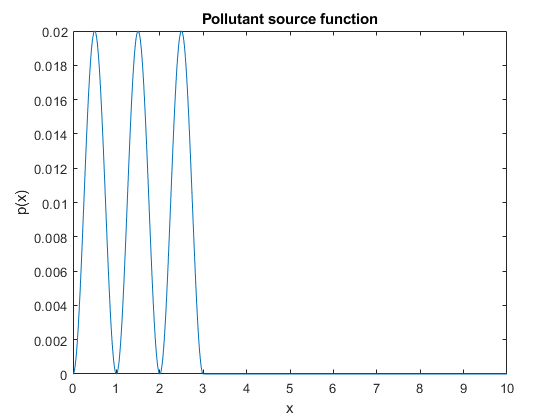

n = 1000;
x = linspace(0,L,n+1);
x_int = x(2:end-1);      % these are the interior points used for finite differences
dx = x(2)-x(1);

p_src = @(x) 0.01 * (cos(2*pi*x + pi) + 1).* (x<=3);

figure(1); clf
plot(x,p_src(x))
xlabel('x')
ylabel('p(x)')
title('Pollutant source function')

Because our boundary conditions give us $u_0 =u_n =0$, we have $n-1$ unknowns at the interior grid points. Recall that the governing equations are given by


$$0= \left(  - \frac{a}{\Delta x} 
\cdot \textbf A_1 + \frac{D}{(\Delta x)^2}\cdot\textbf A_2 \right)\textbf u + \textbf p$$


where

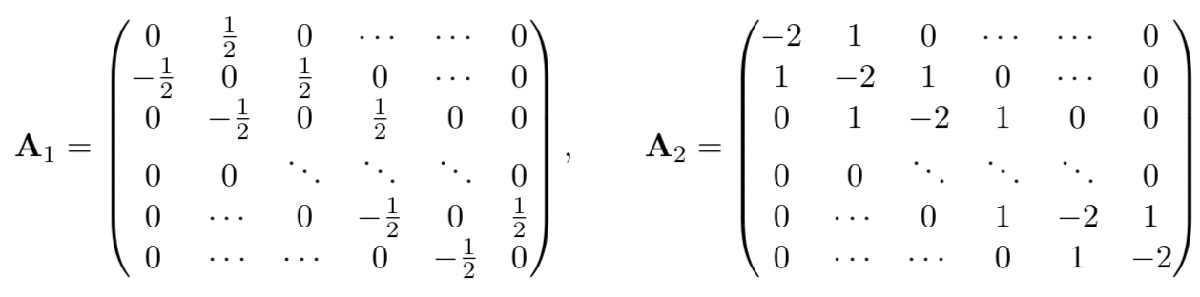

#### (0) Please include all the names of your group members here:

Kyle McGraw

#### (1) Please write some code in the for loop below to fill in the appropriate coefficients of ${\mathit{\mathbf{A}}}_1$ and ${\mathit{\mathbf{A}}}_2$ for the interior equations:

As discussed in class, we can write our difference approximations for $u_x$ and $u_{xx}$ at the grid points as matrices ${\mathit{\mathbf{A}}}_1$ and ${\mathit{\mathbf{A}}}_2$ times the vector $\mathit{\mathbf{u}}$ containing the values of our approximations at the grid points, $u\left(x_i \right)$. We will write some code to build these matrices in the next block.

% initialize all matrices as all zeros
A1 = zeros(n-1);
A2 = zeros(n-1);

% first row
A1(1,2) = 1/2;
A2(1,1:2) = [-2 1];

% loop through rows corresponding to i = 2..n-2 and set the
% coefficients of A1 and A2 appropriately
for i = 2:n-2
    A1(i,i-1:i+1) = [-1/2 0 1/2];
    A2(i,i-1:i+1) = [1 -2 1];
end

% last row
A1(end,end-1) = -1/2;
A2(end,end-1:end) = [1 -2];

#### (2) Now that that's done, we can assemble our overall matrix $\mathit{\mathbf{A}}$ and use MATLAB's backslash command to solve for the steady-state solution:

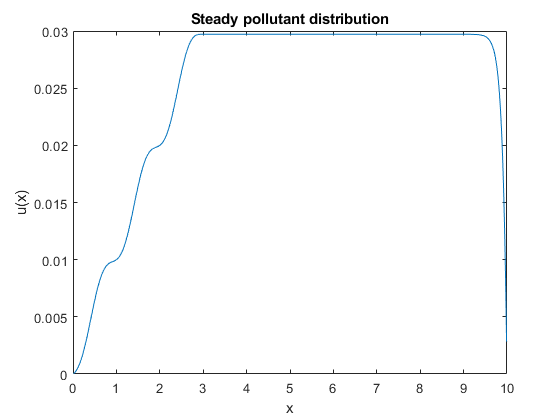

A = -a/dx*A1+D/dx^2*A2;

p = p_src(x_int');
u = -A\p;

figure(2); clf
plot(x_int,u)
xlabel('x')
ylabel('u(x)')
title('Steady pollutant distribution')

#### (3) Look at the plotted solution: what are its main features? Can you explain these features in terms of the physics represented by the convection, diffusion, and reaction terms?

We see the boundary conditions of 0 at either end of the clean river to start and the river flowing into the ocean. Since we have a pollutant source function with three peaks, we get three rises in pollutants in our river starting at those location. The rise is not as steep as the pollutant source curve as we have the river moving the pollutant down stream. Since we also have diffusion of the pollutants both up and down stream, we don't just have all the pollutants going down river but will have the slightly less steep curves. Once we pass all the sources, the concentration will flatten out from diffusion and the diffusion up and down stream will be the same giving up the flat part of the graph. Finally, the ocean quickly drops it back to zero as the pollutant diffuses.